# 学習用音声ファイルの分割

Copyright 2020 Michio Inoue

基本戦略

- サンプルレートは 44.1 kHz に統一

- 拡張子は mp4 に変更（mp3 での保存ができないため）

- 各ファイルファイルは 20 秒に分割（最大 8 つまで）

- ただ、データ量が少ない 'grieg' （8ファイル）は各ファイル最大 128 個まで、 'wagner' (14ファイル)は各ファイル最大 73 個（128/14*8）までとする。

## 事前準備

ディレクトリ情報の確保

settings = jsondecode(fileread('..\settings.json'));
newdir = settings.TRAIN_PROCESSED_DIR

newdir = '../data/processed/train'

origdir = fullfile(settings.RAW_DATA_DIR, 'train')

origdir = '..\data\train'

学習データ（作曲家名など）のリストを読み込み（DataExploration.mlx で作成済み想定）

load(fullfile(settings.PROCESSED_DATA_DIR, 'trainDataSummary.mat'),'traindata');

分割済みファイルを保存するフォルダ作成

if ~exist(newdir,'dir')
    mkdir(newdir);
end

分割後ファイルの長さ（秒）と周波数設定

duration = 20; % 20 sec
Fs = 44100; % 44.1 hHz

## データ分割処理

データストア作成

ds = audioDatastore(origdir);

進捗表示用

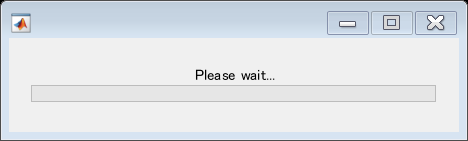

f = waitbar(0,"Please wait...");

各ファイル毎に処理

NofFiles = length(ds.Files);
for ii=1:NofFiles
    % 進捗表示
    waitbar(ii/NofFiles,f,"Processing training data (" + ii + "/" + NofFiles + ")");
    
    % ファイルへの絶対パス
    filepath = ds.Files{ii};
    % ファイル名だけ抽出
    [~,name,~] = fileparts(filepath); % ファイル名
    
    % 作曲家情報
    idx = traindata.filename == (string(name) + ".mp3");
    artist = traindata.artist(idx);
    
    % 作曲家によって最大分割数を操作
    if string(artist) == "grieg"
        NofParts = 128;
    elseif string(artist) == "wagner"
        NofParts = 73; %round(128/count*8);
    else
        NofParts = 8;
    end
    
    % 音声データ読み込み
    [audioData,fs] = audioread(filepath);
    if fs == 22050 % 22.05 kHz のものがあれば 44 kHz にアップサンプリング
        audioData = resample(audioData,Fs,fs); %
    end
    % 分割前のデータ点数
    N = length(audioData);
    
    % 分割後音声のデータ点数
    NofPoints = duration*Fs;
    
    % NofPoints 以下のデータしかない場合はそのまま1つファイル保存して終了
    if N < NofPoints
        audiowrite(fullfile(newdir, name + "-1.mp4"), audioData, Fs);
        continue % 次のファイルへ
    end
    
    % 最大分割数分のデータ量が無い場合は、単純に 20 秒ずつに取れるだけ分割
    % 例：20 sec * 8 = 160 sec 以下の場合
    if N <= NofParts*NofPoints
        % 20 secs ごとに分割
        NofSegs = floor(N/NofPoints);
        for kk=1:NofSegs
            dataseg = audioData(NofPoints*(kk-1)+1:NofPoints*kk);
            audiowrite(fullfile(newdir, name + "-" + string(kk) + ".mp4"), dataseg, Fs);
        end
    else
        % それ以外の場合は均等に 20 秒区間を抽出
        for jj=1:NofParts
            tmp = audioData((jj-1)*round(N/NofParts)+1:(jj-1)*round(N/NofParts)+NofPoints);
            audiowrite(fullfile(newdir, name + "-" + jj + ".mp4"), tmp, Fs);
        end
    end
end
waitbar(ii/NofFiles,f,"Finished: Processing training data");